# `Nonlinear Lateral Vehicle Model`

`Simulink & Matlab`

`Brian Lesko, Graduate Researcher and Teaching Associate, Masters of mechanical engineering student `

`Autonomy in Vehicles ECE 5553  | Ohio State University | 2/20/2023`

`with use of Robust Controls of Mechatronic Systems by Dr. Levent Guvenc`

# `Contents `

`1. Introduction `

`2. The Nonlinear Lateral Model`

`    a) Free Body Diagram*`

`    c) Block Diagram`

`    d) Model Parameters`

`3. Conclusions and future work`

`4. Functions`

# `Introduction`

`    This report contains longitudinal vehicle modeling work formatted as a markdown file. Code, written in MATLAB, is contained in this file to run SIMULINK models, which must be downloaded separtely, if contained in the correctly named folder in the workspace path, no changes are necessary to repeat the same results. This report includes projects from the following Ohio State University courses: Vehicle Systems and Control Mechanical Engineering (ME) 8352 and Autonomy in Vehicles Electical and Computer Engineering (ECE) 5553 offered and completed by Brian Lesko in Autumn 2022 and Spring 2023 respectively in person at Ohio State's Columbus Campus. Topics covered in this report are partly inspired by these courses as well as the book Robust Controls of Mechatronic Systems by Dr. Levent Guvenc. `

### Lateral Dynamics Simulink Models	

Investigate the nonlinear and linear single-track models provided in same Simulink diagram. 						

[L,g,Lr,Lf,Cf,Cr,Cs,m,J,mu,R,Vref,alphaf,a11,a12,a21,a22,b11,b12,b21,b22,e2] = getLateralParameters();

The Linear and Nonlienar Lateral models, top level diagram

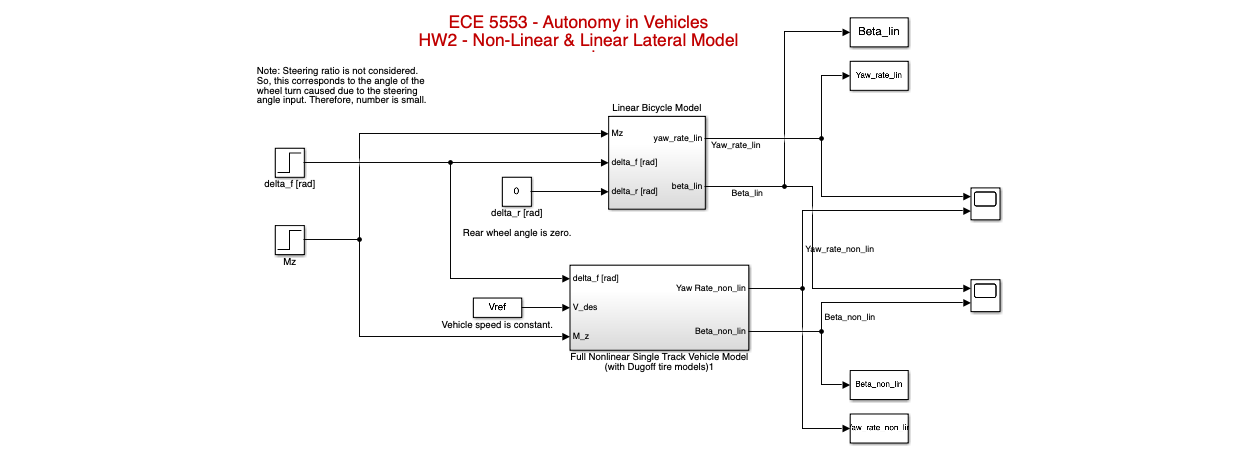

The linear model used is 

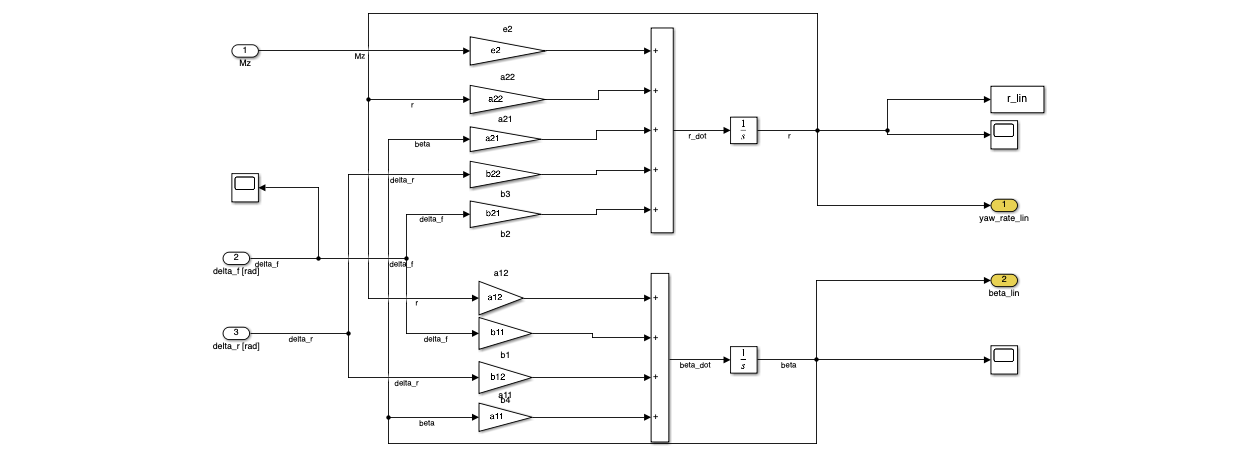

		The nonlinear model used is

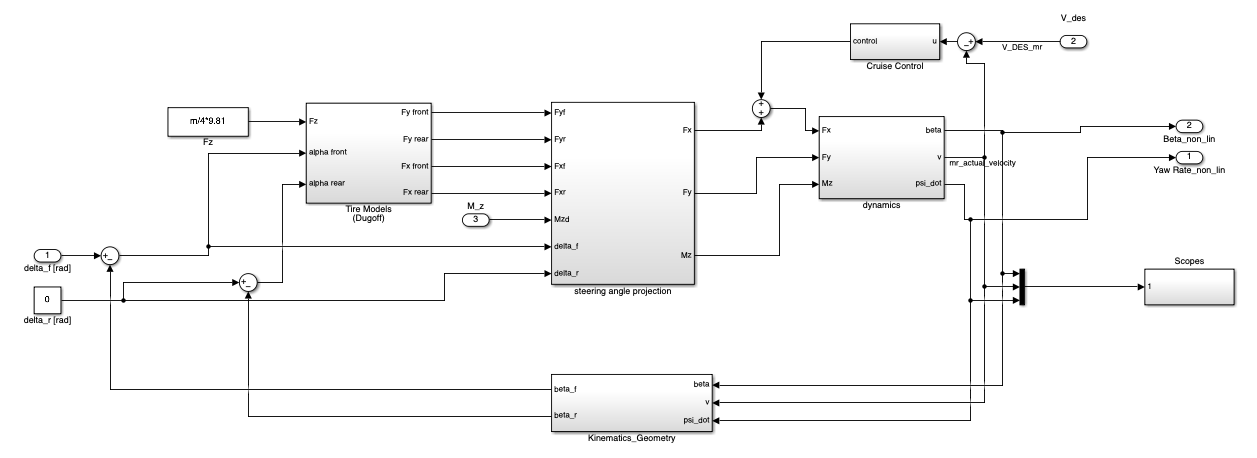

#### Vehicle Parameters are stored in 

%[L,g,l_r,l_f,m,Fz,C_f,C_r] = getUndersteerVehicleParameters()
%[L,g,l_r,l_f,m,Fz,C_f,C_r] = getOversteerVehicleParameters()

**Plotting the Vehicle's Yaw Velocity Gain vs speed from the gradient**

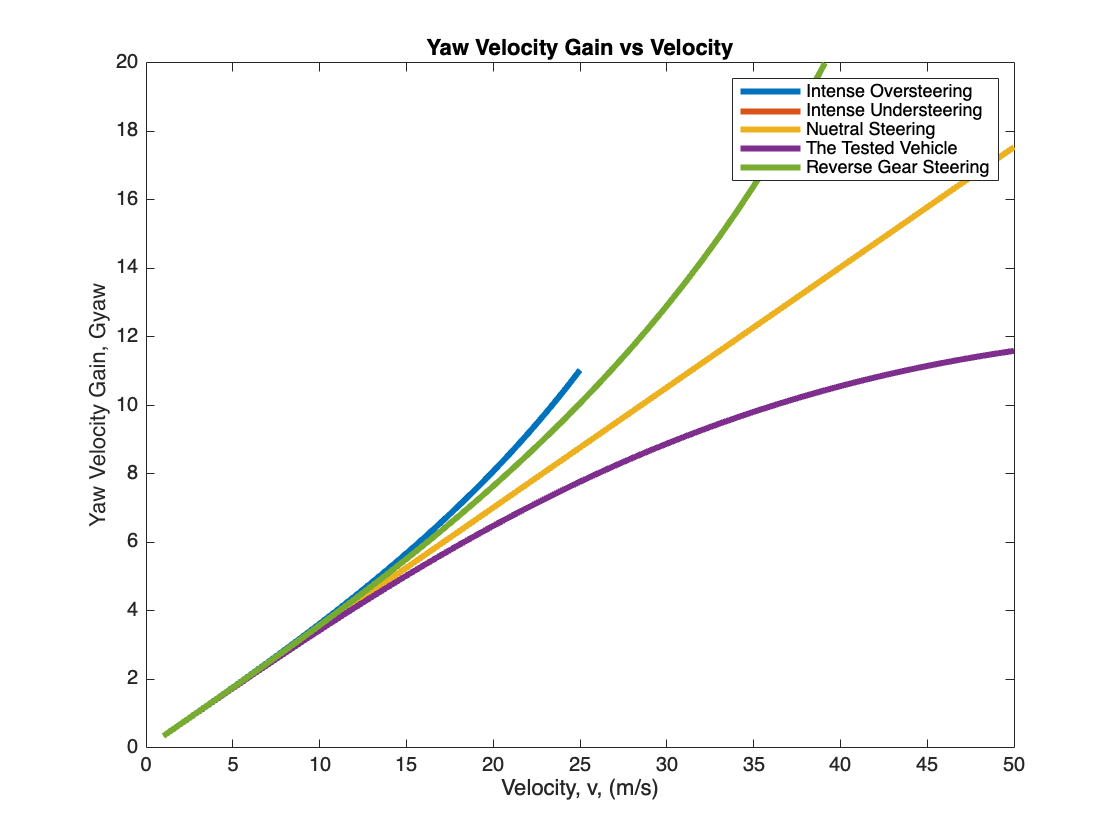

close all, figure
plotUndersteerGradients()

## Step Steering Input on Lateral Models

Steering Input of 5.7 degrees at 1 second, model comparison 								

Run Simulation 

sim('lateral_models')

Yaw Rate Comparison

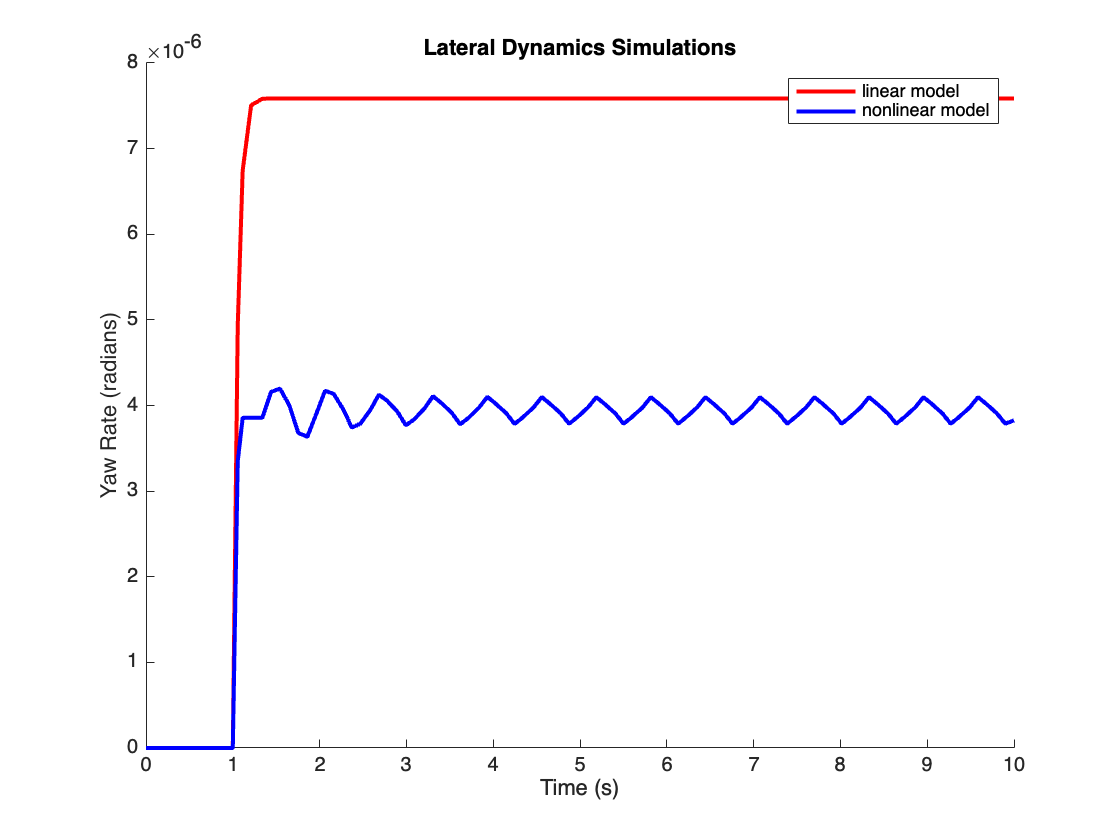

figure, hold on
plot(time,yawRateLin,'r','linewidth',2)
plot(time,yawRateNonLin,'b','linewidth',2)
legend('linear model','nonlinear model'), title('Lateral Dynamics Simulations'),xlabel('Time (s)'), ylabel('Yaw Rate (radians)')

Side Slip angle Comparison 

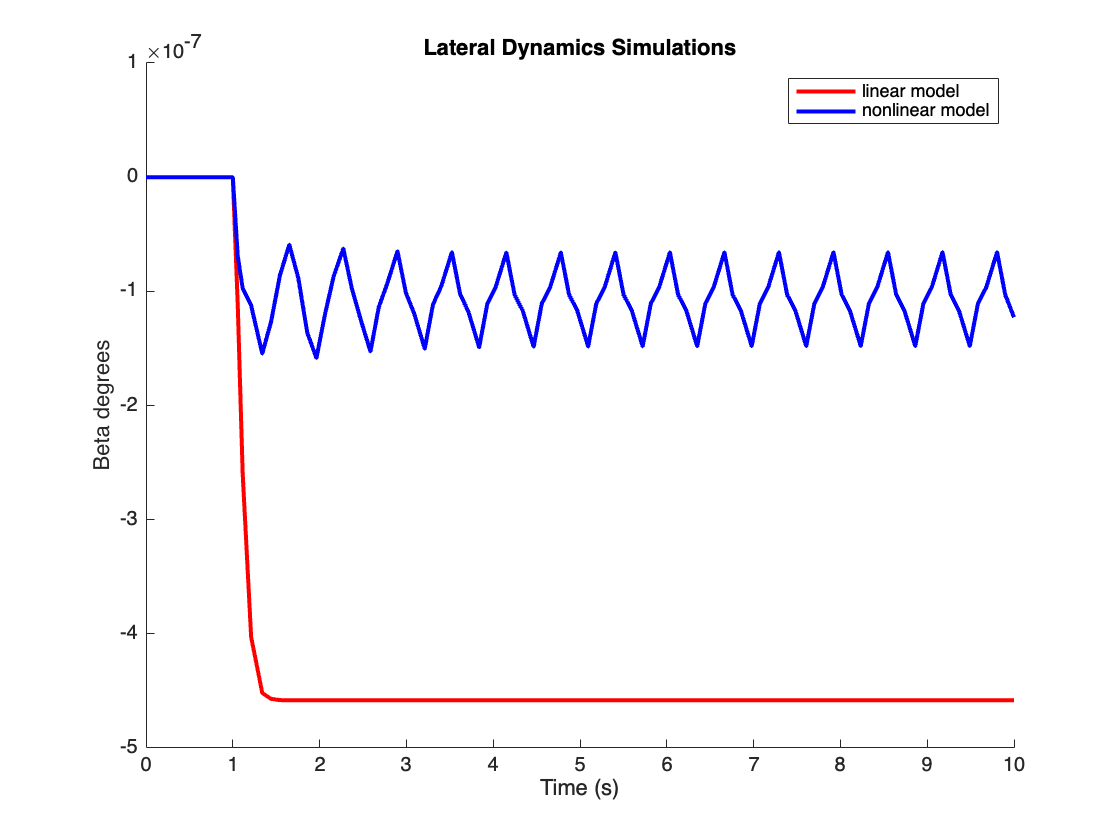

figure, hold on
plot(time,betaLin,'r','linewidth',2)
plot(time,betaNonLin,'b','linewidth',2)
legend('linear model','nonlinear model'), title('Lateral Dynamics Simulations'),xlabel('Time (s)'), ylabel('Beta degrees')

## Yaw Disturbance comparison

For a Yaw moment disturbance at t = 1

Run Simulation 

sim('lateral_models')
figure, hold on
plot(time,yawRateLin,'r','linewidth',2)
plot(time,yawRateNonLin,'b','linewidth',2)
legend('linear model','nonlinear model'), title('Lateral Dynamics Simulations'),xlabel('Time (s)'), ylabel('Yaw Rate (radians)')


figure, hold on
plot(time,yawRateLin,'r','linewidth',2)
plot(time,yawRateNonLin,'b','linewidth',2)
legend('linear model','nonlinear model'), title('Lateral Dynamics Simulations'),xlabel('Time (s)'), ylabel('Yaw Rate (radians)')

function [L,g,l_r,l_f,m,Fz,C_f,C_r] = getUndersteerVehicleParameters()
    % Parameters
    L=2.85; % Distance between the axles [m]
    g=9.81; % 
    l_r = 1.55;% Distance from the center of gravity of the vehicle (CG) to the rear axle
    l_f = 1.3; % Distance from the center of gravity of the vehicle (CG) to the front axle
    m = 2000; % Mass of the vehicle [kg]
    Fz = (m*g)/4; % Vertical force is 1/4 on each tire
    
    C_f = 3e5; % Cornering Stiffness of Front Tires
    C_r = 3e5; % Cornering Stiffness of Rear Tires
end 

function [L,g,l_r,l_f,m,Fz,C_f,C_r] = getOversteerVehicleParameters()
    %Parameters
    L=2.85; % Distance between the axles [m]
    g=9.81; % 
    l_r = 1.55;% Distance from the center of gravity of the vehicle (CG) to the rear axle
    l_f = 1.3; % Distance from the center of gravity of the vehicle (CG) to the front axle
    m = 2000; % Mass of the vehicle [kg]
    Fz = (m*g)/4; % Vertical force is 1/4 on each tire
    
    C_f = 3e5; % Cornering Stiffness of Front Tires
    %Reduced rear cornering stiffness to make Kus < 0;
    C_r = 2e5; % Cornering Stiffness of Rear Tires
end 

function plotUndersteerGradients()
    %Oversteer, Yaw Velocity
    [L,g,l_r,l_f,m,Fz,C_f,C_r] = getOversteerVehicleParameters();
    Kus = (l_r/C_f/L - l_f/C_r/L)*m*g;
    v_critical = sqrt(-L*g/Kus);
    v = 1:0.5:25; %velocity
    Gyaw_O = v./(L+Kus*v.^2/g);
    plot(v,Gyaw_O,'LineWidth',3), hold on
    
    %Understeer, Yaw Velocity
    [L,g,l_r,l_f,m,Fz,C_f,C_r] = getUndersteerVehicleParameters();
    Kus = (l_r/C_f/L - l_f/C_r/L)*m*g;
    v = 1:1:50; %velocity
    Gyaw_U = v./(L+Kus*v.^2/g);
    plot(v,Gyaw_U,'LineWidth',3)
    
    %Nuetral Vehicle
    Kus_nuetral = 0;
    Gyaw_nuetral = v./(L+Kus_nuetral*v.^2/g);
    plot(v,Gyaw_nuetral,'LineWidth',3)
    
    %The given Vehicle 
    [L,g,l_r,l_f,m,Fz,C_f,C_r] = getUndersteerVehicleParameters();
    Kus = (l_r/C_f/L - l_f/C_r/L)*m*g;
    Gyaw = v./(L+Kus*v.^2/g);
    plot(v,Gyaw,'LineWidth',3)
    
    [L,g,l_r,l_f,m,Fz,C_f,C_r] = getUndersteerVehicleParameters();
    Cf_r = C_r;
    Cr_r = C_f;
    Lf_r = l_r;
    Lr_r = l_f;
    Kus_reverse = (Lr_r/Cf_r/L - Lf_r/Cr_r/L)*m*g; %static yaw rate gain under steady state conditions (s=0) steering input*Kus = yaw rate, at ss only
    Gyaw = v./(L+Kus_reverse*v.^2/g);
    plot(v,Gyaw,'LineWidth',3)
    xlabel('Velocity, v, (m/s)'),ylabel('Yaw Velocity Gain, Gyaw'),title('Yaw Velocity Gain vs Velocity'), hold on
    legend('Intense Oversteering','Intense Understeering','Nuetral Steering','The Tested Vehicle','Reverse Gear Steering')
    axis([0 50 0 20])
end 

function [L,g,Lr,Lf,Cf,Cr,Cs,m,J,mu,R,Vref,alphaf,a11,a12,a21,a22,b11,b12,b21,b22,e2] = getLateralParameters()
    %% Parameters
    L=2.85; % Distance between the axles [m]
    g=9.81; % 
    Lr = 1.55;% Distance from the center of gravity of the vehicle (CG) to the rear axle
    Lf = 1.3; % Distance from the center of gravity of the vehicle (CG) to the front axle
    Cf = 3e5; % Cornering Stiffness of Front Tires x2
    Cr = 3e5; % Cornering Stiffness of Rear Tires x2
    Cs = 1.5e5; % Cornering Stiffness
    m = 2000; %Mass of the vehicle [kg]
    J = 3700; %Yaw moment of Inertia
    mu = 0.7; %Dry coefficient of Friction
    R = 0.3; % Wheel radius
    Vref = 20; % Constant vehicle velocity.
    alphaf = 0.1; % Steering wheel angle rad/sec
    %%
    
    %Linear Parameters Calculation
    a11 = -(Cr+Cf)/(m*Vref);
    a12 = -1-((Cf*Lf-Cr*Lr)/(m*Vref^2));
    a21 = (Lr*Cr-Lf*Cf)/J;
    a22 = -((Cf*Lf^2)+(Cr*Lr^2))/(Vref*J);
    b11 = Cf/(m*Vref);
    b12 = Cr/(m*Vref); %delta_r parameter
    b21 = Cf*Lf/J;
    b22 = Cr*Lr/J; %delta_r parameter
    
    e2 = 1/J; % For yaw moment term
end 
